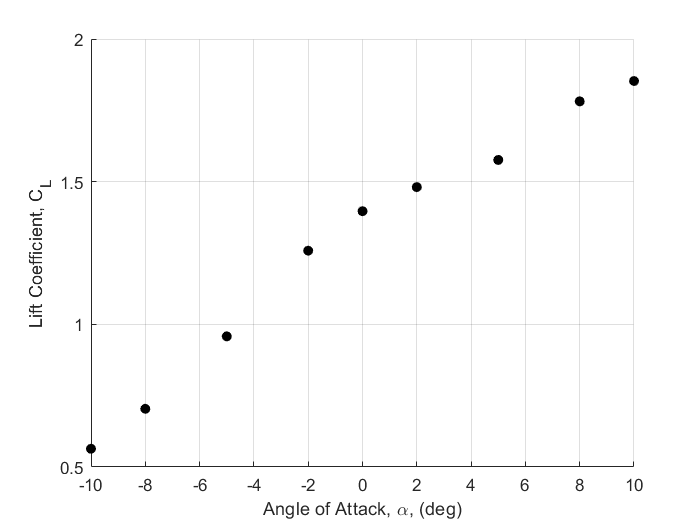

clear all; clc

% Data settings
Speed = 10;
RPM = 8;
tilt = 20;

% Aircraft Geometry
S = 0.03469846; %m^2 (1578 ft^2/65^2)

% Atmospheric Conditions
rho = 1.21; %kg/m^3

AoA = [-10, -8, -5, -2, 0, 2, 5, 8, 10];

for i = 1:length(AoA)

    thisAoA = AoA(i);

    % Get file names
    fileName = "u_"+ string(Speed) + "_a" + string(thisAoA) + "_r" + string(RPM) + "_t" + string(tilt) + "_calibrated" + ".mat";
        
    x = load (fileName);
    
    % Get CL, CD, AoA
    CL(i) = ( x.Fz*cosd(thisAoA) + x.Fx*sind(thisAoA) ) / (0.5*rho*x.V^2*S);
    CD(i) = ( x.Fz*sind(thisAoA) - x.Fx*cosd(thisAoA) ) / (0.5*rho*x.V^2*S);
    
    clear x;
end

% Lift Curve graph
figure
scatter(AoA,CL, 'filled','black')
xlabel('Angle of Attack, \alpha, (deg)')
ylabel('Lift Coefficient, C_{L}')
grid on 

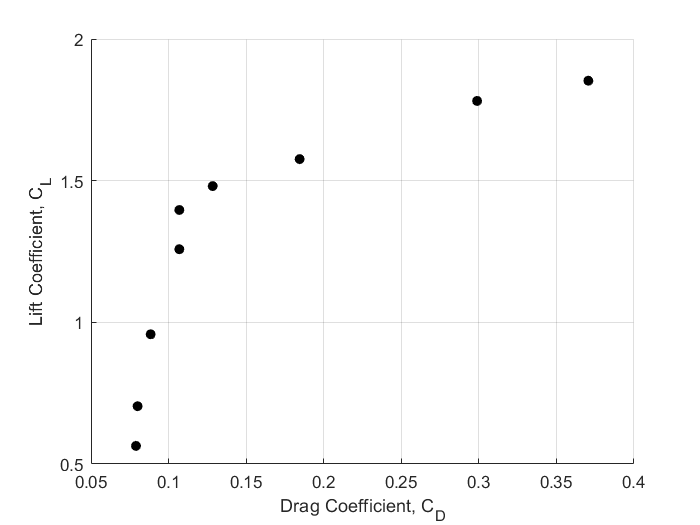


% Drag Polar
figure
scatter(CD,CL,'filled','black')
xlabel('Drag Coefficient, C_{D}')
ylabel('Lift Coefficient, C_{L}')
grid on